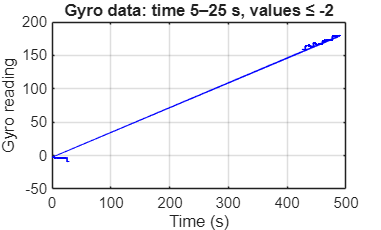

fname = 'gyro2 CoolTerm Capture (Untitled_0) 2026-03-07 19-45-12-776.txt';

data = readmatrix(fname);

t = data(:,1);
y = data(:,2);

figure
plot(t, y, '-b', 'LineWidth', 1)
xlabel('Time (s)')
ylabel('Gyro reading')
title('Gyro data: time 5–25 s, values ≤ -2')
grid on

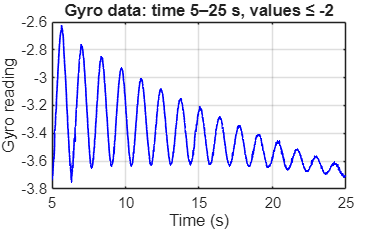


mask = (t >= 5) & (t <= 25) & (y <= -2);

t_sel = t(mask);
y_sel = y(mask);

figure
plot(t_sel, y_sel, '-b', 'LineWidth', 1)
xlabel('Time (s)')
ylabel('Gyro reading')
title('Gyro data: time 5–25 s, values ≤ -2')
grid on

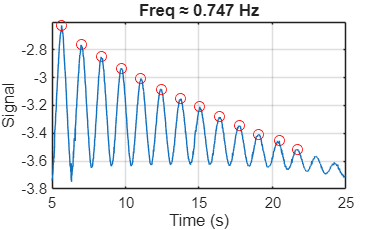

[~,locs] = findpeaks(y_sel, t_sel, 'MinPeakProminence', 0.12);
periods = diff(locs);
periods = periods(isfinite(periods) & periods>0);
fn_time = 1/mean(periods);

length = 9.8/(fn_time^2);

figure
plot(t,y), hold on
axis([5 25 -3.8 -2.6])
plot(locs, interp1(t,y,locs), 'ro')
xlabel('Time (s)'), ylabel('Signal'), title(sprintf('Freq ≈ %.3f Hz',fn_time))
grid on, hold off


disp("natural frequency = " + fn_time)

natural frequency = 0.74706


disp("length = " + length)

length = 17.5597
